# Interpolatory $\mathcal{H}_\infty$-approximation for pH-systems (IHA-PH)

## Introduction

In model order reduction of pH-systems we face three goals: preserving the pH-structure, approximating the dynamics of the original model accurately with respect to certain system norms and keeping the numerical effort as low as possible. IHA-PH beeing a hybrid method combines the advantages of interpolatory and optimization-based methods leading to higher accuracies compared to the former and less computational costs in contrast to the latter. The interpolatory $\mathcal{H}_\infty$-approximation framework was introduced by Castagnotto et al. in [1] for general LTI systems.  

### The idea

We start with a reduced order model $\tilde{\Sigma}$ obtained via rational interpolation. To decrease the $\mathcal{H}_\infty$-error, we introduce additional degrees of freedom by perturbing the feedthrough matrices, that were not altered during projection,


$$\mathbf{N}_{new} = \mathbf{N}_{old} + \mathbf{\Delta}_N$$


$\mathbf{S}_{new} = \mathbf{S}_{old} + \mathbf{\Delta}_S$.

If we choose the remaining systems matrices according to Theorem 2 in [4] the obtained system is pH and certain interpolation conditions are retained. The new degrees of freedom can be optimized with respect to the $\mathcal{H}_\infty$-error. IRKA-PH (for a short introduction see this [IRKA-PH demo file](matlab:open('./demo_irkaPH.mlx'))) is observed to produce good $\mathcal{H}_\infty$-approximants, although it is a $\mathcal{H}_2$-inspired method. Thus, IRKA-PH is suitable as initial reduction method.

Parameterizing $\mathbf{\Delta_N}$ and $\mathbf{\Delta_S}$ with the parameter vector $\theta \in \mathbb{R}^{m^2}$, partioned as $\theta = [\theta_N^\mathbf{T},\theta_S^\mathbf{T}]^\mathbf{T}$, that takes into account structural constraints, we end up with the optimization problem

$\theta^\ast = \arg \min \limits_{{\theta \in \mathbb{R}^{m^{2}}}} \left\| \mathbf{G} - \hat{\mathbf{G}}(\cdot,\theta) \right\| _{\mathcal{H}_\infty}$,    (1)

where $\mathbf{G}(s)$ and $\hat{\mathbf{G}}(s,\theta)$ denote the transfer functions of the full and reduced order model, respectively.

### Algorithmic details

#### Cost function

The direct minimization of (1) with respect to $\theta$ comes with several problems. Two main disadvantages are that the computation of the $\mathcal{H}_\infty$-norm is computationally expensive and the $\mathcal{H}_\infty$-norm depends nonsmoothly on the parameter vector $\theta$. To circumvent these problems we apply the leveled-least-squares approach proposed in [5]. Let $S := \{s_j\}_{j=1}^{n_s} \subset \text{i}\mathbb{R}$ denote a set of $n_s$ sample points and let $\sigma_k(\cdot)$ denote the $k$-th singular value of a matrix. We minimize

$L(\gamma,\mathbf{G},\hat{\mathbf{G}}(\cdot,\theta),S) := \frac{1}{\gamma}\sum\limits_{s_j \in S} \Bigg( \sum \limits_{k=1}^{m} \bigg(  \big[\sigma_k \big( \mathbf{G}(s_j) - \hat{\mathbf{G}}(s_j,\theta) \big) - \gamma \big]_+ \bigg)^2 \Bigg)$    (2)

with respect to $\theta$, where


$$[\cdot]_+ : \mathbb{R} \to \overline{\mathbb{R}^+}, x \mapsto \begin{cases}
		x & \text{if } x\ge 0,\\
		0 & \text{if } x<0
	\end{cases}$$


for decreasing values $\gamma > 0$. Minimizing $L$ instead of the $\mathcal{H}_\infty$-error is computational less demanding since $\mathbf{G}$ has to be evaluated only once at S in the beginning of the optimization step. Remaining computations only involve the ROM. Additionally, L depends smoothly on $\theta$ enabling gradient based optimization. The value $\gamma$ plays a curcial role in the minimization of (2). It is updated either according to a fixed sequence or by a bisection algorithm.

#### Initialization and adaption of $S$

The set of sample points $S$ can be fixed or adapted dynamically. For the latter one, a reasonable initialization is necessary. One way to do so is a greedy strategy introduced in [4]. Since this requires repeated evaluations of the $\mathcal{H}_\infty$-norm and therefore is computationally demanding, we utilize the fact that we initially reduce the full order model with IRKA-PH. The eigenvalues of the model obtained from IRKA-PH will have eigenvalues close to the peaks of $\mathbf{G}(\text{i}\omega)$, which will in turn produce peaks in the transfer function of the ROM. Thus, we project these eigenvalues onto the imaginary axis to cover closer surroundings of local maxima of $\mathbf{G}(\text{i}\omega)$.

Instead of taking into account a large amount of sample points, we apply the logarithmic sampling adaption from [5]. The procedure automatically adds sample points to $S$ inbetween existing ones if necessary.

#### CIRKA-PH

The evaluation of $\mathbf{G}(s)$ at the sample points in $S$ can be computationally demanding for large-scale models $\mathbf{\Sigma}$. We can avoid this problem with the application of CIRKA-PH (for a short introduction see this [CIRKA-PH demo file](matlab:open('./demo_cirkaPH.mlx'))) instead of IRKA-PH. The method produces a medium-sized model function $\mathbf{\Sigma}^\mu$ of dimension $n_\mu$ at no additional cost. This surrogate model is often much smaller than the original model and in general provides a better fit compared to the reduced-order model. Thus, its transfer function $\mathbf{G}^\mu(s)$ can be evaluated with significantly less computational effort.

#### Optimization

For optimization we apply third-party software: Manopt and Granso. The user can choose between both. While Manopt comes with several optimization algorithms, the algorithm implemented in *granso* is a sequential quadratic method utilizing Broyden-Fletcher-Goldfarb-Shanno quasi-Newton Hessian approximations for solving nonsmooth and nonconvex optimization problems and is chosen by default.

#### $\mathcal{H}_\infty$-norm computation

Our implementation computes the $\mathcal{H}_\infty$-norm at the end of the calculation and several times during optimization if the direct optimization approach is chosen. We provide different methods to calculate the norm. By default the method from [8] is chosen. Alternatively the Control System toolbox command *norm* or the methods from [9] and [10] are possible.

### Pseudo-Code

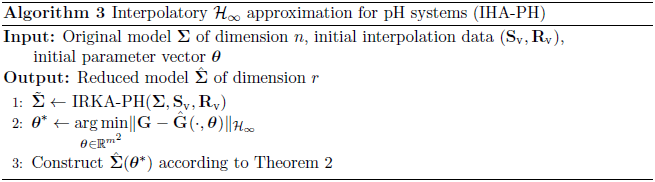

Image source: [2]

## Toolbox Implementation

The MORpH toolbox provides an implementation of the IHA-PH algorithm called iha*PH*.

It combines multiple subroutines such as *irkaPH*,* cirkaPH, adaptPH* and third party software such as *granso, linorm_subsp, Manopt*.

For more information, refer to the documentation:

help ihaPH

  ihaPH - obtaining a H-infinity tuned reduced PH system via feedthrough optimization
 
  Syntax:
    sysr = ihaPH(sys, redOrder)
    sysr = ihaPH(sys, s0)
    sysr = ihaPH(sys, s0, options)
    sysr = ihaPH(sys, s0, Rt)
    sysr = ihaPH(sys, s0, Rt, options)
    [sysr, status, output] = ihaPH(sys,redOrder)
 
  Description:
        sysr = ihaPH(sys, redOrder) returns a reduced PH system with given order redOrder
 
        sysr = ihaPH(sys, redOrder, s0, Rt) returns a reduced PH system
                 with given order redOrder, with s0 and Rt as the initial shifts
                 and tangential directions for cirkaPH
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:      phs object
        - redOrder: desired reduced order
        - s0:       (alternatively) initial guess for shifts for cirkaPH
        *Optional 

## Examples

### Ladder Network

The first example considered here is a SISO Ladder Network with an architecture as shown below:  

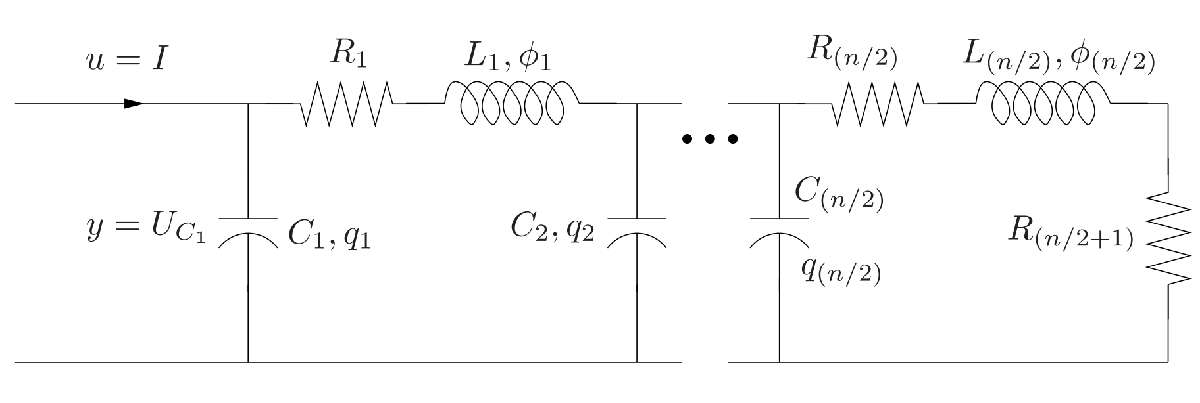

Image source: [6]

We consider a model with dimension $n = 100$, i.e. 50 inductances ($L_i = 0.1\text{H}$), 50 capacitors ($C_i = 0.1\text{F}$) and 51 resistances ($R_i=3\Omega$).

sys = setup_LadderNetworkSystem(100,0.1,0.1,3)

sys =   phs with properties:

               J: [100×100 double]
               R: [100×100 double]
               Q: [100×100 double]
               G: [100×1 double]
               E: [100×100 double]
               P: [100×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 100
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


ih*aPH* in its simplest form is called by providing the system to reduce and the desired reduced order:

warning('off')
sysr = ihaPH(sys, 10)

IHAPH stopped after 1 iterations
Elapsed time: 0.41s


sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @ihaPH
            info: [1×1 struct]
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0.0071
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


### Mass-Spring-Damper model

Next we consider a MIMO Mass-Spring-Damper model with the following architecture:

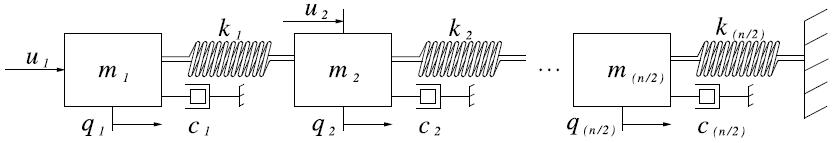

Image source: [7]

We consider a model with dimension $n = 100$, i.e. 50 masses ($m=4 \text{kg}$), 50 springs ($k = 4 \text{kgs}^{-2}$), and 50 dampers ($d = 1 \text{kgs}^{-1}$) .

sys = setup_MassSpringDamperSystem(100, 4, 4, 1,'MIMO')

sys =   phs with properties:

               J: [100×100 double]
               R: [100×100 double]
               Q: [100×100 double]
               G: [100×2 double]
               E: [100×100 double]
               P: [100×2 double]
               S: [2×2 double]
               N: [2×2 double]
            Opts: [1×1 struct]
             dim: 100
          isMIMO: 1
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


### Options

Since IHA*-PH* is such a high-level algorithm, it provides many (nested) options. The levels of options are:

- Top level (iha*PH*): e.g. initial guess for $\theta$, optimization strategies, maximum number of optimization steps

- Second level (*irkaPH, cirkaPH, granso*): e.g. convergence criteria of IRKA, update strategies, solver options

- Third level (*arnoldiPH*): e.g. structure preservation strategy

- Fourth level (*phs*): e.g. switching on/off input validation

You can find more information on the respective options by having a look at the documentation, e.g.

help cirkaPH

  CIRKA - Confined Iterative Rational Krylov Algorithm for port-Hamiltonian systems
 
  Syntax:
        sysr                 = cirkaPH(sys, redOrder)
        sysr                 = cirkaPH(sys, s0)
        sysr                 = cirkaPH(sys, s0, Rt)
        sysr                 = cirkaPH(sys, s0, ..., Opts)
        [sysr, V, W, s0, Rt, sysm, s0mTot, nLU] = cirkaPH(sys, ... )
 
  Description:
        This function executes an adapted version of the Confined Iterative Rational Krylov
        Algorithm (CIRKA) as proposed by Castagnotto et al. in [1,2].
 
        The algorithm is based on constructing a model function, i.e. a
        surrogate representing the full oder model locally about some
        frequencies, and running IRKAPH with respect to the surrogate model.
        The model function is updated until convergence.
 
 
  Input Arguments:
        *Required Input Arguments:*
        -sys:			full 

To provide these options, use nested structs. As example, the following code changes the initial parametervector, to run more iterations, give intermediate output, permit the use of the model funciton, change the $\mathcal{H}_\infty$-norm computation method, etc.:

Opts = struct();
Opts.S0 = [1e-3;1e-3;1e-3];         % Initial values for theta_S
Opts.M0 = 1e-3;                     % Initial values for theta_N
Opts.maxIter = 800;                 % Maximum number of iterations
Opts.printLevel = 1;                % Define intermediate output
Opts.modelFct = 1;                  % Enable use of model function
Opts.hinfnorm.method = 'matlab';    % Hinf-norm computation method
Opts

Opts = struct with fields:
            S0: [3×1 double]
            M0: 1.0000e-03
       maxIter: 800
    printLevel: 1
      modelFct: 1
      hinfnorm: [1×1 struct]


sysr = ihaPH(sys,10,Opts)

###### QUADPROG NOTICE ####################################################################
#  GRANSO requires a quadratic program (QP) solver that has a quadprog-compatible         #
#  interface, as defined by MATLAB's own QP solver quadprog (available in the             #
#  Optimization Toolbox).  MOSEK also provides a quadprog-compatible interface to their   #
#  QP solver and, of course, one may always write a quadprog-compatible wrapper for the   #
#  QP solver of one's choice.                                                             #
#                                                                                         #
#  Note that GRANSO's performance, in terms of efficiency and/or optimization quality,    #
#  may vary depending upon which QP solver is employed, particularly for nonsmooth        #
#  constrained optimization problems.                                                     #
#                                                                               

sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @ihaPH
            info: [1×1 struct]
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×2 double]
               E: [10×10 double]
               P: [10×2 double]
               S: [2×2 double]
               N: [2×2 double]
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 1
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


### Output

*ihaPH* provides more outputs than the reduced order system:

[sysr, status, output] = ihaPH(sys, 10)

IHAPH stopped after 47 iterations
Elapsed time: 1.57s


sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @ihaPH
            info: [1×1 struct]
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×2 double]
               E: [10×10 double]
               P: [10×2 double]
               S: [2×2 double]
               N: [2×2 double]
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 1
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


status = struct with fields:
                    final: [1×1 struct]
                     best: [1×1 struct]
                  H_final: [4×4 double]
               stat_value: 3.3712e-09
                    iters: 25
             BFGS_updates: [1×1 struct]
                 fn_evals: 56
         termination_code: 0
    quadprog_failure_rate: 0
               iterations: 47


output = struct with fields:
    cirkaPH: [1×1 struct]


status is a struct containing information about the optimization step. The output struct contains information from all other used subfunctions (for example the reduced system obtained from irkaPH).

Additionally the reduced order system gives some additional information which makes its creation more transparent:

sysr.method         % Method with which the system was created (should be @ihaPH)

ans = function_handle with value:
    @ihaPH


sysr.parameters     % Execution parameters (options, sample points, etc.)

ans = struct with fields:
             hinfnorm: [1×1 struct]
    initialPopulation: []
         optimization: 'llsq'
            printNorm: 0
           printLevel: 0
              cirkaPH: [1×1 struct]
               irkaPH: [1×1 struct]
                  phs: [1×1 struct]
               granso: [1×1 struct]
               manopt: [1×1 struct]
              adaptPH: [1×1 struct]
             modelFct: 0
     adaptiveSampling: 3
            bisection: 0
              summary: 1
     initialReduction: 'cirkaPH'
                 plot: 0
        cmptRealBasis: 'svd'
              maxIter: 500
      finiteDiffOrder: 11
          tolgradnorm: 1.0000e-08
               tolLSA: 0.5000
         samplePoints: [19×1 double]
                gamma: [1 0.5000 0.2000 0.1000 0.0500 0.0200 0.0100 0.0050 0.0020 1.0000e-03 5.0000e-04 2.0000e-04 1.0000e-04 5.0000e-05 2.0000e-05 1.0000e-05 5.0000e-06 2.0000e-06 1.0000e-06 5.0000e-07 2.0000e-07 1.0000e-07]
             flag_opt: 'granso'
         tolBisec

sysr.info           % Additional information, e.g. Hinf norm, final gamma, computation times

ans = struct with fields:
                  dims: [1×1 struct]
         tOptimization: 0.9711
            tReduction: 0.5859
                  time: 1.5704
           tEvaluation: 0.0013
    numAdaptiveSamples: 0
                 gamma: 0.0500


Explanation of the info entries:

- *dims*:    relevant system dimensions

- *numAdaptiveSamplePoints*:    number of sample points added by logarithmic sampling adaption (only logarithmic sampling adaption)

- *gamma*:    final value $\gamma$ (only leveled-least-squares approach)

## References

[1] A. Castagnotto, C. Beattie, and S. Gugercin, "Interpolatory methods for $\mathcal{H}_\infty$ model reduction of multi-input/multi-output systems", MS&A, 349-365, 2017.

[2] T. Moser, M. Bonauer, P. Schwerdtner and B. Lohmann, "Model Reduction of Port-Hamiltonian Systems via Feedthrough Optimization", 2022

[3] P. Schwerdtner and M. Voigt. Structure Preserving Model Order Reduction by Parameter Optimization. arXiv Preprint arXiv:2011.07567. 2020. URL: https://arxiv.org/abs/2011.07567.

[4] Beddig, Benner, Dorschky et. al., "Model Reduction for Second-Order Dynamical Systems Revisited", PAMM, vol. 19, 2019.

[5] P. Schwerdtner, M. Voigt. Adaptive Sampling for Structure Preserving Model Order Reduction of Port-Hamiltonian Systems. IFAC-PapersOnLine 54(19) (2021), pp. 143-148.

[6] R. V. Polyuga, "Model reduction of port-Hamiltonian systems", PhD thesis, University of Groningen, 2010

[7] Polyuaga et al. (2012), "Effort- and flow-constraint reduction methods for structure preserving model reduction of port-Hamiltonian systems", Systems & Control Letters 61(3).

[8] Aliyev, Benner, Mengi, Schwerdtner, and Voigt, "Large-Scale Computation of $\mathcal{L}_\infty$ by a Greedy Subspace Method", SIAM Journal on Matrix Analysis and Applications, 38(4):1496–1516, 2017.

[9] Benner, Voigt, "A structured pseudospectral method for H-infinity-norm computation of large-scale descriptor systems", Math. Control Signals Syst., 26:303–338, 2014.

[10] Castagnotto, Varona, Jeschek, Lohmann, "sss & sssMOR: Analysis and reduction of large-scale dynamic systems in MATLAB" *at - Automatisierungstechnik*, vol. 65, no. 2, 2017, pp. 134-150.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Maximilian Bonauer    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)